Final Project EAS 4610 

Emily Tribby Sophia Sparks 

a tragic story 

%Load Met data from usgs 
data= readmatrix("met_data_march.csv");
data(:,1)=[];
Ta=data(:,1); %temperature dry bulb (deg C)
Tw=data(:,2); %temperature wet bulb (deg C)
U2= data(:,3)/2.237; %windspeed in mph-> meters/s 
C=data(:,4);% cloud coverage (in tenths) 
Kd= data(:,5); %Solar irradiance data (watt hour /m^2/day )CONVERT TO W/m^2)
P=data(:,6); %pressure kpa

%preallocation 
I=linspace(60,90,31); % julian day 
t= I; %time in julian days 
z=-4:1:0; %depth in meters 
nt=length(t);
nz=length(z);
T=nan.*ones(nz,nt+1);
Tbound=nan.*ones(nz-2,nt+1);
S=nan.*ones(nz,nt+1);
phi = nan.*ones(1,nt+1);
K = nan.*ones(nz,1);

%constants 
A=[323343600, 210124300, 52497200, 600, 100]; %area in m^2 for depths 1m-4m 
Cw=4.18/1E-6;  %volumetric heat capacity (J*m^3*degC^-1
Beta=0.4; %proportion of shortwave radiation that is absorbed in the surface layer (40%)
n=1.2; %light extiction coefficient for water (m^-1) 
theta=47.3371; %latitude (deg N) 
sig= 5.67E-8; %stepfan boltzman constant (W/m^2K^4) 
td= 86400; %number of seconds in a day
km=2.0204*1E-9*td;  %molecular diffusion of water (m^2d^-1) 
A1= 0.3; %longwave albedo of the lake surface 
Rmw=0.622; %ratio molecular weight of water vapor/dry air = 0.622.
lambda= 2.45; %latent heat of water vaporization, [MJ kg−1]
Cp= 1.005/1000; %specific heat of air at contsant pressure (MJ/kg*K)
k= 0.4; %Von Karmon's constant 
P0= 1;%P0 is the neutral value of the turbulent Prandtl number 
Akm=323.3; %surface area of lake (km^2) 
N= 0.029*Akm^-0.05; %N empiracally determined mass transfer coefficient (mm s m^-1 kPa^-1) (26)
g=9.8; %m/s^2 acceleration due to gravity 
esp= 0.97; % emissivity
rhoe=1; %density of the evaporated water vapor

%set "source" term 
for i = 1: width(S)
    S(:,i)= 1./(A*Cw);
end 
S(1,1) = 0; 
%set surface boundary condition 
for i= 1: nt
    Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
end 
%set bottom boundary 
Tbound(end, :)= Tbound(1,1)-1; %sufficiently turbid such that it can be assumed to be insulated at bottom 
%set intial condition (T0 for all z)
T(1,1)=Tbound(1,1);  
T(end,1)= Tbound(end,1); 
T(2:end-1,1)= Tbound(1,1)-0.5; %assume polymicitic lake thus little mixing


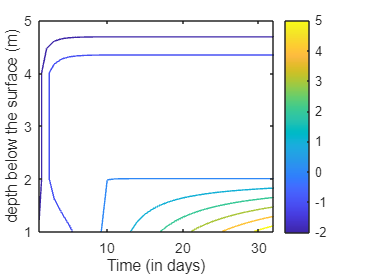


for i=2:nt
%dependant on U2, I, Ta, Tw
Ts=surftemp(I(i));
a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
delta=-23.4*cos(360*(I(i) + 10)/365); %solar declination determined by Oke, 1987 (15)
cos_H=-tan(theta)*tan(delta);
if isreal(acos(cos_H))
    H= acos(cos_H);%half-day length (units?) (14) 
else
    H=3.14;
end 
b = a + sin(theta)*sin(delta); %(17)
c=cos(theta)*cos(delta);%(18)
B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)
if b^2 -c^2 > 0 %16
    F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
else 
    F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
end 
As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 

Tk = Ts+273;%temperature of surface in kelvin 
ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)
ks=  6.6*sqrt(sin(theta))*U2(i)^-1.84;% a  latitudinally dependent parameter of the Ekman profile, (7) 
rhof= (1-1.9549E-5*abs(Tk-277)^1.68)*10^3; %density of fresh water (kg/m^3)
Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 



tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
tk2= 1-(375.15/(Tw(i)+273));
e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air
if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
    esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
else 
    esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
end 
Ld= esp_a*sig*(Ta(i) +273)^4; % (20) 
Lds= (1-A1)*Ld; %long wave radiation from the atmosphere (23)
Lu= esp*sig*(Ts+273)^3 ;%stefan boltzman law (24) longwave rad from lake surface 
Le=1.91846E6*((Ts +273)/(Ts +329.09))^2; %latent hear fo vaporization (MJ kg^-1) 
E= N*U2(i)*(e0-ea); %evaporation (mm) 
Qe= rhoe*Le*E; %(29) rho is density of the evaporated water vapor (= 1kg m^-3) and Le is the latent heat of vaporization (MJ kg^-1) 
R= gamma*(Ts-Ta(i))*(e0-ea); %bowen ratio R
Qh= R*Qe; % flux of sensible heat (31)


%Tbound 
%for y = 2:size(S(1))
   %Con = phi(i)*A(y)-phi(i-1)*A(y-1);
   %S(y,:) = Con*S(y,:);
%end
%%% Now for the relevant numerical method 
for x=1:nz 
    Ri= (-1 + sqrt(1+ (40*Nbv^2*(k^2)*(z(x)^2))/ ws^2*exp(-2*k*z(x))))/20; %richardson number 
    K(x) = km + eddy_dif(z(x),k,ws,ks,Ri,P0);
    exp(-n*z(x))*Ks;
    phi(i)= (1-B)*Ks*exp(-n*z(x)); % heat source term in (W/m^2) Beer's Law (2)
end 

%Cd = K*dt/dz^2
Cd = 0.5; 

end 


for l=1:nt
    for m=2:nz
        T(m,l+1) = T(m,l) + Cd*(T(m,l)-T(m-1,l)-2*T(m,l)+T(m-1,l)) + S(m,l); 
    end 

    T(1,l+1) = surftemp(I(l));
    T(end,l+1) = T(end,1);
end

contour(T)
ylabel("depth below the surface (m)")
xlabel("Time (in days)")
colorbar

functions 

function K=eddy_dif(z,k,ws,ks,Ri,P0)%(m^2*d^-1)
    K= (k*ws*z/P0)*exp(-ks*z)*(1+ 37*Ri^2)^-1; 
end 
function Ts= surftemp(I)
 Ts = -2E-06*I^3 - 0.0002*I^2 + 0.3149*I - 19.655; %cubic spline interpolation 
end 
